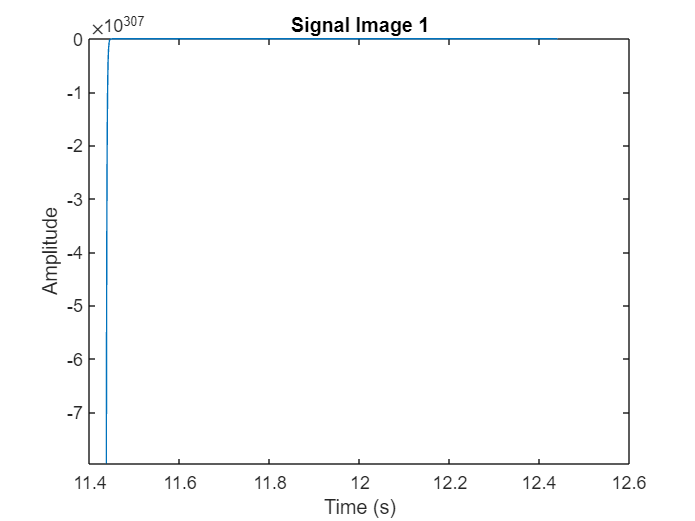

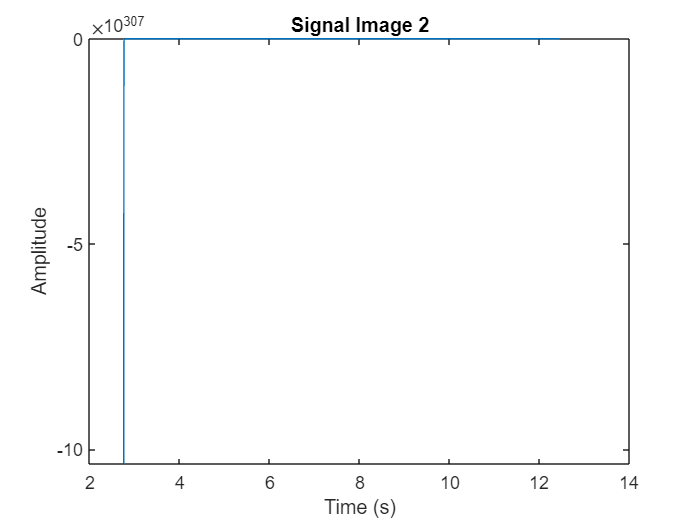

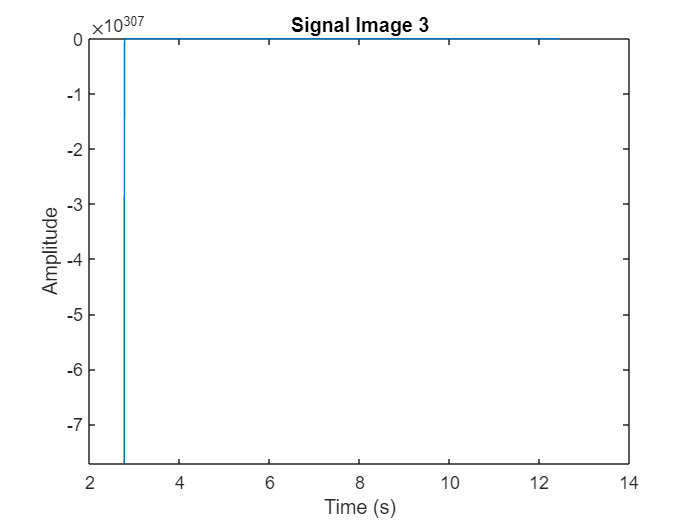

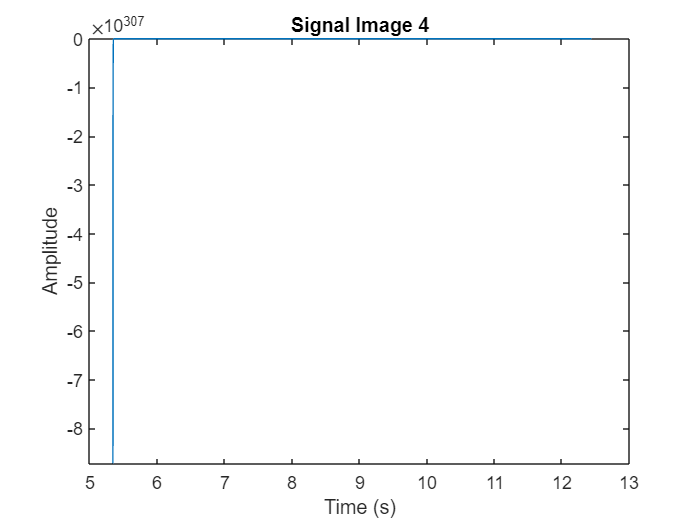

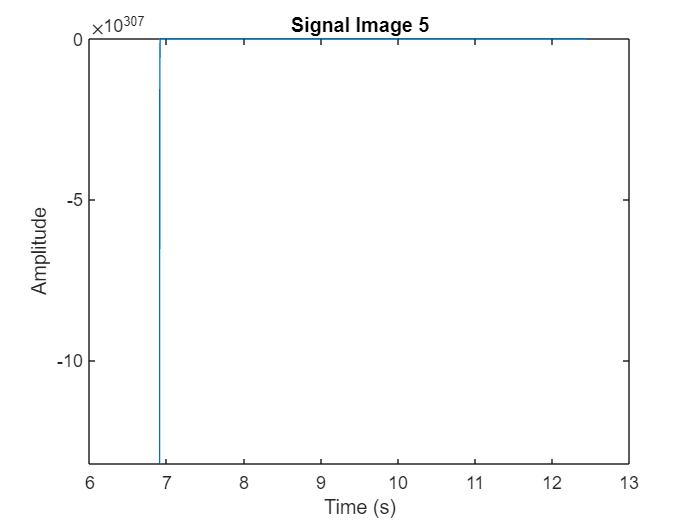

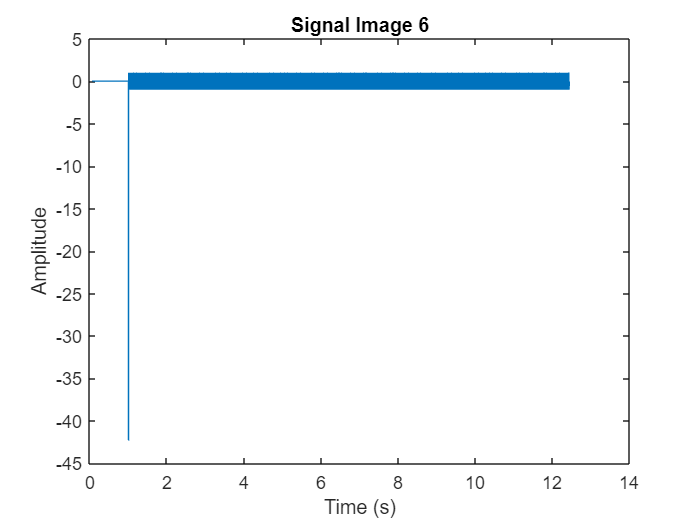

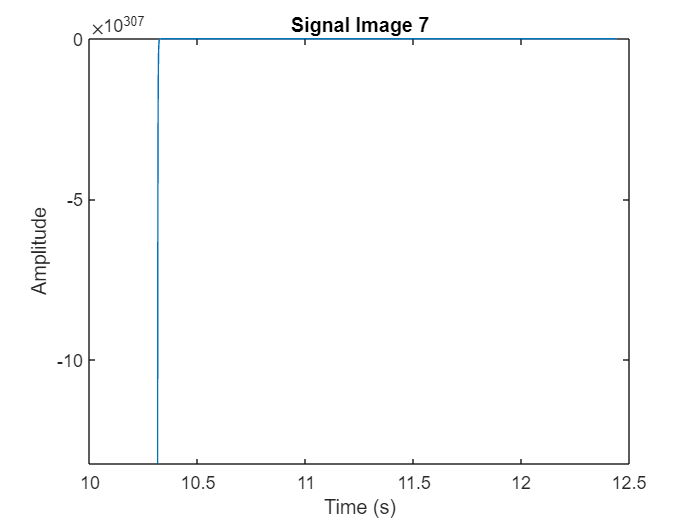

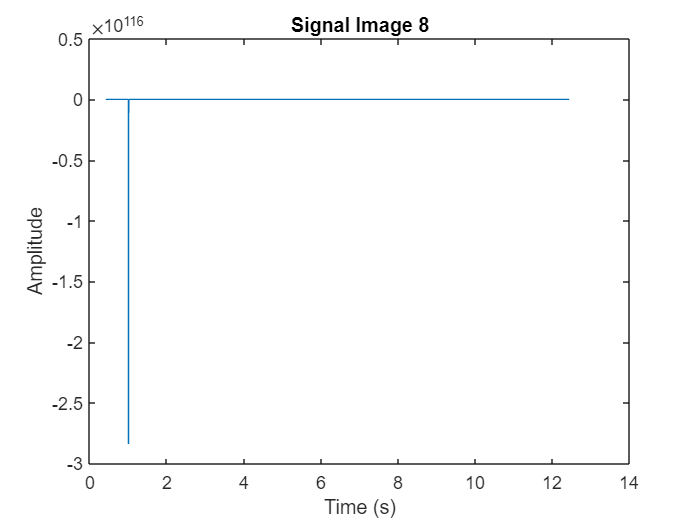

% Parameters
A = 1;                   % Amplitude
f = 50;                  % Frequency in Hz
sampling_rate = 3200;    % Sampling rate in Hz
num_cycles = 622;        % Number of cycles considered

% Time vector
T = 1 / f;                                      % Period of one cycle
duration = num_cycles * T;                      % Total duration of the signal
num_samples = duration * sampling_rate + 1;     % Number of samples
t = linspace(0, duration, num_samples);         % Time vector

% Angular frequency of the sinusoidal signal
omega = 2 * pi * f;
num_signals = 50;

% Generate 50 signal images
for signal_index = 1:num_signals
    % Define random parameters
    alpha = rand() * 0.5 + 0.5;   % Random alpha in [0.5, 1]
    t_alpha = rand() * duration; % Random t_alpha within the duration of the signal
    
    % Calculate the signal
    signal = (sin(omega * t) - alpha * (exp(-750 * (t - t_alpha)) - exp(-344 * (t - t_alpha)))) .* u(t - 1);
    
    % Plot the signal
    figure;
    plot(t, signal);
    xlabel('Time (s)');
    ylabel('Amplitude');
    title(['Signal Image ', num2str(signal_index)]);
end